format long g
% phonename="Pixel4";
gnd=readtable("ground_truth.csv");
obsname='LLH_T.csv';
obs=readtable(obsname);
gnd{:,3}=gnd{:,3}/1000; % ms convert to s
obs{:,4}=floor(obs{:,4})

obs = 1748×4 table
          Lat                 Long                Height            Epoch   
    ________________    _________________    _________________    __________

    37.3958394000237    -122.102705072347     58.0223971605301    1303683548
    37.3956984637384    -122.102695858983     63.9729511272162    1303683549
    37.3956799488857    -122.102733288374      66.653752354905    1303683550
    37.3958000147773    -122.102972784906     19.4987473292276    1303683551
    37.3958012937467    -122.102900583553        12.8251072485    1303683552
    37.3956584537723    -122.103022753363     24.5326259052381    1303683553
    37.3956573012262     -122.10293836398    -8.66748867090791    1303683554
    37.3957374215394    -122.102943790257     12.1312254015356    1303683555
    37.3955467347805    -122.102848664821     8.58606879413128    13036835


wgs84=wgs84Ellipsoid('meter');
[obsE,obsN,obsU]=geodetic2ecef(wgs84,obs{:,1},obs{:,2},obs{:,3});
[gndE,gndN,gndU]=geodetic2ecef(wgs84,gnd{:,4},gnd{:,5},gnd{:,6});
obs.E=obsE;obs.N=obsN;obs.U=obsU;
gnd.E=gndE;gnd.N=gndN;gnd.U=gndU;
gnd{:,3}=floor(gnd{:,3})

gnd = 1999×14 table
        collectionName         phoneName     millisSinceGpsEpoch       latDeg            lngDeg         heightAboveWgs84EllipsoidM    timeSinceFirstFixSeconds    hDop    vDop    speedMps    courseDegree            E                    N                   U        
    _______________________    __________    ___________________    _____________    _______________    __________________________    ________________________    ____    ____    ________    ____________    _________________    _________________    

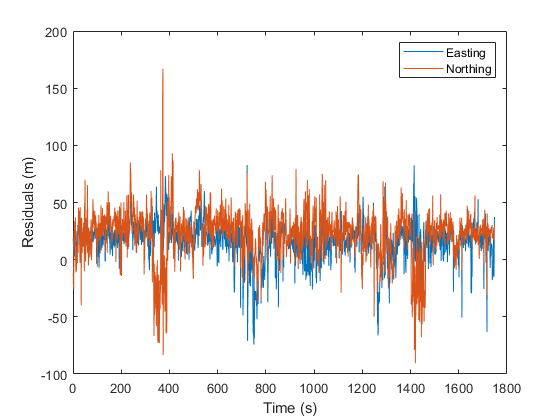

gnd=gnd(:,[1:6 12:14 7:11]);
obs=obs(:,[1:3 5:7 4]);
[ro,co]=size(obs);
vENU=NaN([ro,3]);
obsEpoch=obs{:,co}; % epoch in obs always last var
gndEpoch=gnd{:,3};

for i = 1:ro
    vENU(i,:)=obs{i,4:6}-gnd{gndEpoch==obsEpoch(i),7:9};
end
plot(vENU(:,1))
hold on
plot(vENU(:,2))
legend('Easting','Northing')
xlabel('Time (s)');ylabel('Residuals (m)');
hold off

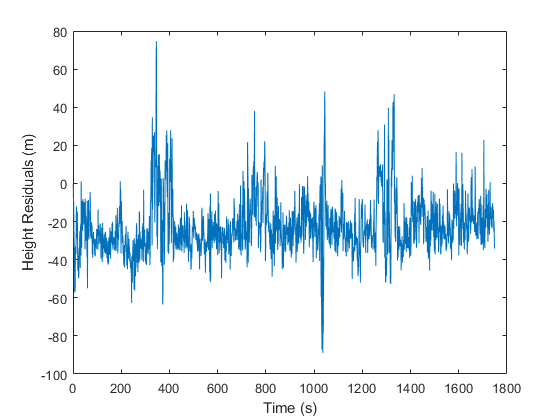

plot(vENU(:,3))
xlabel('Time (s)');ylabel('Height Residuals (m)')

rmse=sqrt(sum(vENU.^2,1,'omitnan')/ro)

rmse =           23.9927438220257          31.2860041826922          26.8425452248604


sqrt(rmse(2)^2+rmse(1)^2)

ans =           39.4267144691107


rmseH=sqrt(rmse(1)^2+rmse(2)^2)

rmseH =           39.4267144691107


rmseV=rmse(3)

rmseV =           26.8425452248604


%for i=1:
%gnd(1:10,:); % polling rate 1/s=1hz
%obs(1:10,:);

